% Declaring the new output variables
% An x, theta_1 and theta_2 values are defined
% The system has the single derivatives of the values
% All of them are state variables and contribute to y0
y0 = [10; 0; 10; 0; 20; 0]

y0 =     10
     0
    10
     0
    20
     0


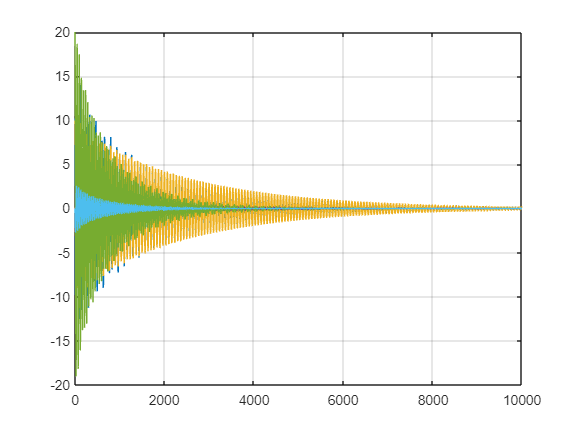

%defining the timespan
    tspan = 0:0.01:10000; 
%using ode45 function for definining a diff eqn
    [t1,y1] = ode45(@twoload,tspan,y0); 
%plotting the function output on a 2D graph
    plot(t1,y1)
    obs
    grid on

function dydt = twoload(t1,y)
M=1000;
m1=100;
m2=100;
l1=20;
l2=10;
g=9.81;
A=[0 1 0 0 0 0; 
    0 0 -(m1*g)/M 0 -(m2*g)/M 0;
    0 0 0 1 0 0;
    0 0 -((M+m1)*g)/(M*l1) 0 -(m2*g)/(M*l1) 0;
    0 0 0 0 0 1;
    0 0 -(m1*g)/(M*l2) 0 -(g*(M+m2))/(M*l2) 0];
B=[0; 1/M; 0; 1/(M*l1); 0; 1/(M*l2)];
Q=[1000 0 0 0 0 0;
   0 1000 0 0 0 0;
   0 0 100 0 0 0;
   0 0 0 100 0 0;
   0 0 0 0 100 0;
   0 0 0 0 0 100];
R=0.1;
[K_Gain_mat, Po_def_mat, Poles] = lqr(A,B,Q,R);
F=-K_Gain_mat*y;
dydt=zeros(6,1);
% y(1)=x;          
dydt(1) = y(2); 
%y(2)=xdot;
dydt(2)=(F-(g/2)*(m1*sind(2*y(3))+m2*sind(2*y(5)))-(m1*l1*(y(4)^2)*sind(y(3)))-(m2*l2*(y(6)^2)*sind(y(5))))/(M+m1*((sind(y(3)))^2)+m2*((sind(y(5)))^2));%X_DD
%y(3)=theta1;
dydt(3)= y(4);
%y(4)=theta1dot;
dydt(4)= (dydt(2)*cosd(y(3))-g*(sind(y(3))))/l1'; %theta 1 Ddot;
%y(5)=theta2; 
dydt(5)= y(6); %theta 2D
%y(6)=theta2dot;
dydt(6)= (dydt(2)*cosd(y(5))-g*(sind(y(5))))/l2; %theta 2Ddot;
end